# cFastCormics (Senescence)

% add all subfolders to path
addpath(genpath(pwd))

% load the data
gxData = readtable('NEW_SenescenceGEM_ControlSen_NoFilter_geneExpressionData.txt');
senescenceData= gxData(:,[1,2,3,5])

senescenceData = 19855×4 table
      Ensembl_GeneID          HGNC_ID        HGNC_GeneSymbol    Senescent_GeneExpression_Level
    ___________________    ______________    _______________    ______________________________

    {'ENSG00000089127'}    {'HGNC:8086' }     {'OAS1'     }                 8.9128            
    {'ENSG00000126709'}    {'HGNC:4054' }     {'IFI6'     }                 527.39            
    {'ENSG00000162692'}    {'HGNC:12663'}     {'VCAM1'    }                 25.489            
    {'ENSG00000104043'}    {'HGNC:13536'}     {'ATP8B4'   }                 1.6619            
    {'ENSG00000167900'}    {'HGNC:11830'}     {'TK1'      }                 1.4123            
    {'ENSG00000118971'}    {'HGNC:1583' }     {'CCND2'    }                 20.755            
    {'ENSG00000111335'}    {'HGNC:8087' }     {'OAS2'     }             

colnames = {'SenescentCell'}

colnames = 1×1 cell array
    {'SenescentCell'}


rownames = table2cell(senescenceData(:,2))

rownames = 19855×1 cell array
    {'HGNC:8086' }
    {'HGNC:4054' }
    {'HGNC:12663'}
    {'HGNC:13536'}
    {'HGNC:11830'}
    {'HGNC:1583' }
    {'HGNC:8087' }
    {'HGNC:1933' }
    {'HGNC:2640' }
    {'HGNC:10618'}
    {'HGNC:4832' }
    {'HGNC:4831' }
    {'HGNC:17111'}
    {'HGNC:53015'}
    {'HGNC:5208' }
    {'HGNC:26072'}
    {'HGNC:4719' }
    {'HGNC:2016' }
    {'HGNC:33747'}
    {'HGNC:2351' }
    {'HGNC:28087'}
    {'HGNC:4555' }
    {'HGNC:9341' }
    {'HGNC:9998' }
    {'HGNC:44112'}
    {'HGNC:21345'}
    {'HGNC:11932'}
    {'HGNC:1723' }
    {'HGNC:1318' }
    {'HGNC:1857' }



% set figure flag: 1 to output and save density plot
figflag = 1;

# Data discretization

## log2-transform the data

% log2-transform the data
signal = log2(table2array(senescenceData(:,4)));

% transform all -Inf to -10000
signal(isinf(signal)) = -10000;

% for each sample
for j = 1:size(colnames,2)
    signal_sample = signal(:,j); % save only current sample
    data_keep = senescenceData(:,j);
    signal_sample = signal_sample(signal_sample>-10000); % remove samples with low expression
end

# Density Plot

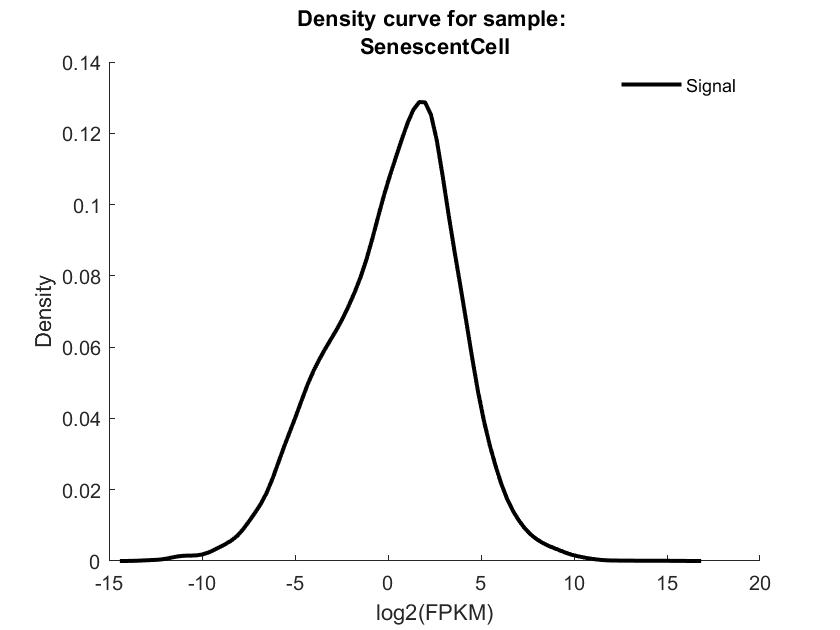

[probability_estimate,xi] = ksdensity((signal_sample)); % get the densities
    
    if figflag;
        figure; hold on
        plot(xi,probability_estimate,'-k','LineWidth',2);
        title({'Density curve for sample: ', colnames{1,j}});
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal'},'Location','best');end

# Create

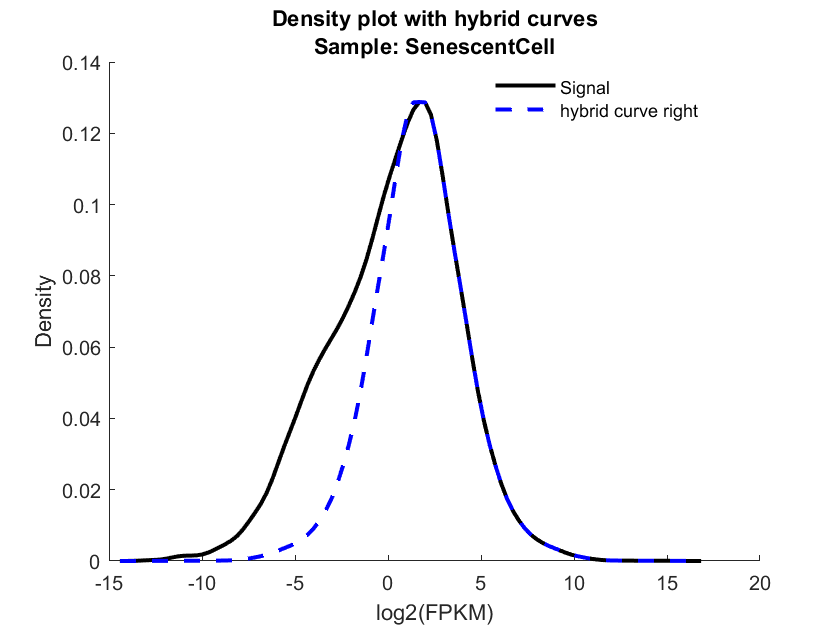

% find the maximum of the density curve
peak_max_idx = (find(probability_estimate==max(probability_estimate)));

% copy right-most side of density curve
max_r_side = probability_estimate(peak_max_idx:end);

% mirror the right side
max_l_side = flip(max_r_side);
hybrid = [max_l_side(1:end-1), max_r_side];


% create hybrid curve
hybrid_curve = zeros(numel(probability_estimate),1);

if numel(hybrid)> numel(probability_estimate)
        hybrid_curve(end+1-numel(hybrid(end-100+1:end)):end)=hybrid(end-100+1:end);
        x = zeros(numel(probability_estimate),1); % create new x-axis
    else
        hybrid_curve(end-numel(hybrid)+1:end) = hybrid;
        x = xi;
    end

 if figflag
        plot(x,hybrid_curve,'b--','LineWidth',2);
        legend({'Signal','hybrid curve right'});
        title({'Density plot with hybrid curves',['Sample: ', colnames{1,j}]},'interpreter','none');end

    
clear peak_max_idx max_l_side max_r_side hybrid

# Create Left Curve (main, right most curve)

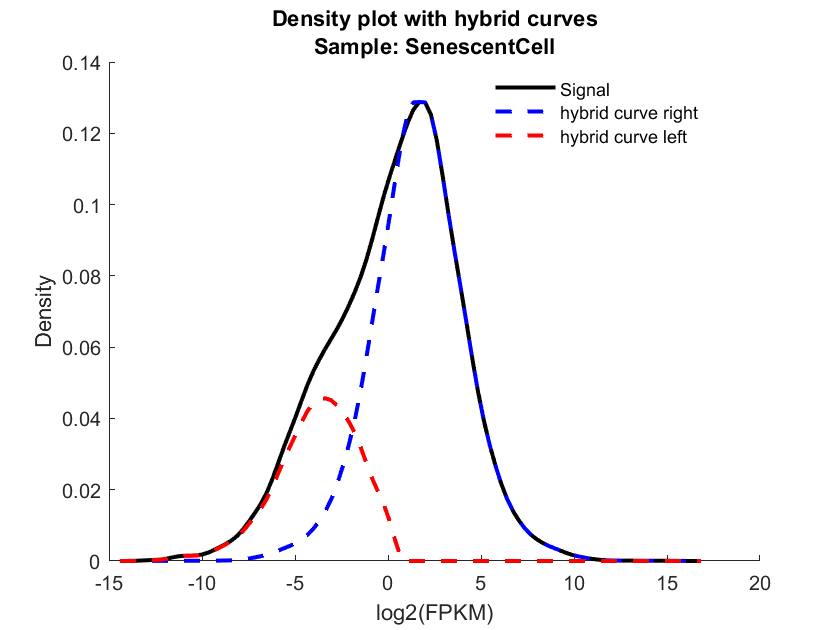

 rest_curve = probability_estimate - hybrid_curve';
    rest_curve(find(rest_curve<0.0001))=0;
        if figflag;
        plot(xi,rest_curve, 'r--','LineWidth',2);
        legend({'Signal','hybrid curve right','hybrid curve left'});end

# Fit of Curves

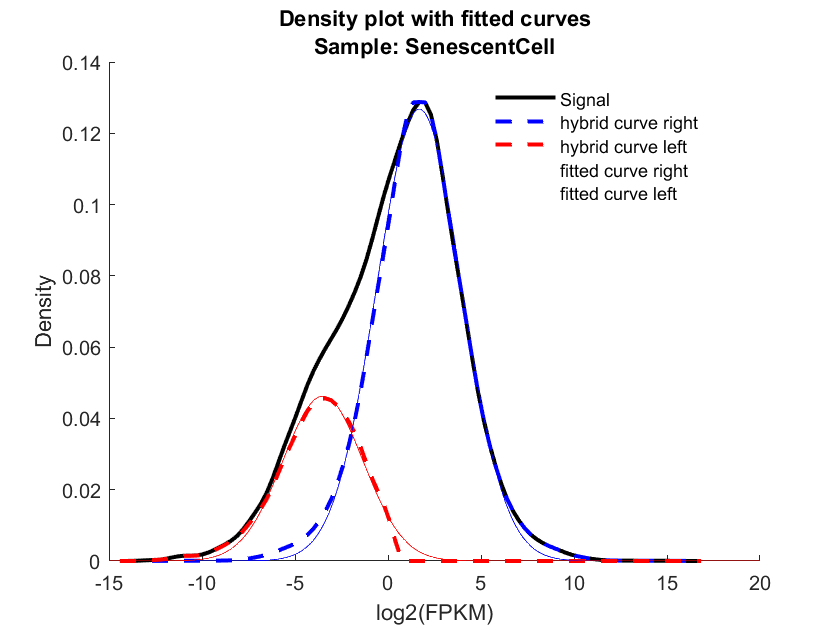

[fitresult_r, ~] = createFit_r(xi, hybrid_curve); % right curve
[fitresult_l, ~] = createFit_l(xi, rest_curve); % left curve
    
    if figflag;
        plot(fitresult_r,'b');
        plot(fitresult_l),'g';
        title({'Density plot with fitted curves',['Sample: ', colnames{1,j}]},'interpreter','none');
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal', 'hybrid curve right', 'hybrid curve left','fitted curve right','fitted curve left'});
  %  saveas(gcf,['Figures\density_', colnames{1,j},'.png']);
    end

#  zFRMA transforms the data and plot the density

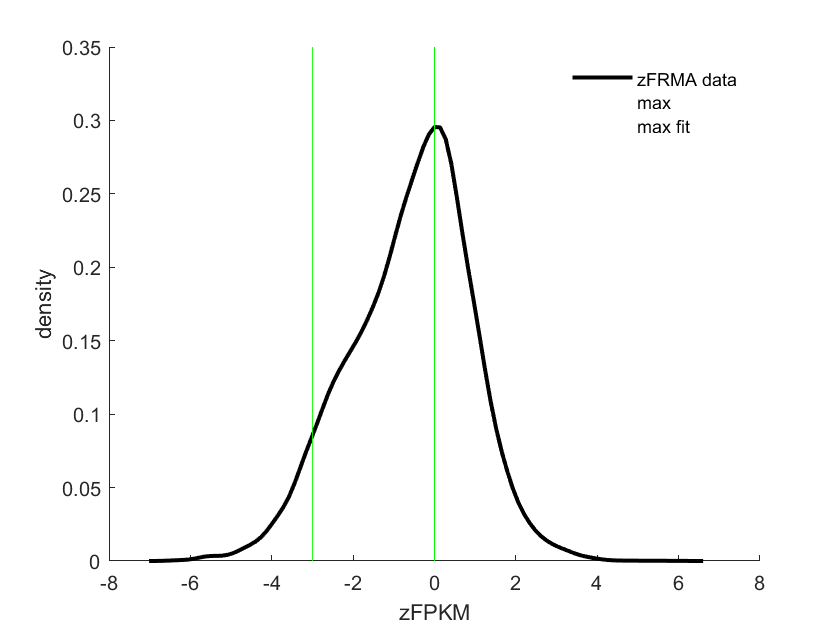

sigma1 = fitresult_r.c1/sqrt(2);
mu1 = fitresult_r.b1; % x-value of right max
    
zFRMA = (signal_sample-mu1)/sigma1;
[yFRMA,xFRMA] = ksdensity(zFRMA);
    
    if figflag; figure;hold on;
        plot(xFRMA,yFRMA,'-k','LineWidth',2);
        xlabel('zFPKM');
        ylabel('density');
        line([0 0], [0.0 0.35],'color', [0,1,0])
        line([-3 -3], [0.0 0.35],'color', [0,1,0]);
        legend({'zFRMA data','max','max fit'});end

    
clear hybrid_curve probability_estimate rest_curve yFRMA xFRMA x xi ans

# Discretization


    zFRMA = (signal(:,j)-mu1)/sigma1; % calculate zFRMA
     
    sigma2 = fitresult_l.c1/sqrt(2);
    mu2 = fitresult_l.b1; % x-value of left max
    mu2_t=(mu2-mu1)/sigma1;
    
    discretized = zFRMA;
    
    e = 0;
    ue = max(-3, mu2_t);
    zFRMA = reshape(zFRMA,size(data_keep,1),size(data_keep,2));
    
    exp_threshold = e;
    unexp_threshold = ue;
    exp=find(discretized>=exp_threshold);
    not_exp=find(discretized<=unexp_threshold);
    unknown = find(discretized<exp_threshold & discretized>unexp_threshold);
    
    discretized(unknown)    = 0;    % unknown expression is set to 0
    discretized(not_exp)    = -1;   % non-expression is set to -1
    discretized(exp)        = 1;    % expression is set to 1
    
    discretized = (reshape(discretized,size(data_keep,1),size(data_keep,2)));
    discretized_keep(j,:) = discretized'; % save for each sample
    
    clear fitresult_l fitresult_r data_keep e exp exp_threshold mu1 mu2 mu2_t not_exp sigma1 sigma2 signal2 signal_sample ue unexp_threshold unknown zFRMA

discretized=discretized_keep';
clear j discretized_keep signal
%close all


# FastCormics with Medium and Models 

load cRecon204.mat  % consistent Recon 2.04 model, obtained by running FASTCC (Vlassis et al., 2014)
load medium_example % need to define medium for the cells used here
load dico_ML.mat % dictionary to map the rownname identifier to the genes in the model

pplsDict = readtable('peoplesOwnDictonary.txt');

workersDict = pplsDict(:, 2);
workersDict(:, 2) = pplsDict(:, 1);

workersDict.Properties.VariableNames{1} = 'SYMBOL';
workersDict.Properties.VariableNames{2} = 'HGNC'

workersDict = 46889×2 table
       SYMBOL             HGNC     
    _____________    ______________

    {'A1BG'     }    {'HGNC:5'    }
    {'A1BG-AS1' }    {'HGNC:37133'}
    {'A1CF'     }    {'HGNC:24086'}
    {'A1S9T'    }    {'HGNC:6'    }
    {'A2M'      }    {'HGNC:7'    }
    {'A2M-AS1'  }    {'HGNC:27057'}
    {'A2ML1'    }    {'HGNC:23336'}
    {'A2ML1-AS1'}    {'HGNC:41022'}
    {'A2ML1-AS2'}    {'HGNC:41523'}
    {'A2MP1'    }    {'HGNC:8'    }
    {'A2MR'     }    {'HGNC:9'    }
    {'A2MRAP'   }    {'HGNC:10'   }
    {'A3GALT2'  }    {'HGNC:30005'}
    {'A4GALT'   }    {'HGNC:18149'}
    {'A4GNT'    }    {'HGNC:17968'}
    {'A12M1'    }    {'HGNC:1'    }



freeMindsDict = readtable('freeMindsDict.txt');

slavMindsDict = freeMindsDict(:, ["NCBIGeneID" "HGNCID"]);
% slavMindsDict(:, 1) = num2str(table2array(slavMindsDict(:, 1)));
slavMindsDict{1, 1} = {'1'} % THIS is so that MATLAB stops being a bitch

slavMindsDict = 46892×2 table
    NCBIGeneID        HGNCID    
    __________    ______________

    {'1'     }    {'HGNC:5'    }
    {'503538'}    {'HGNC:37133'}
    {'29974' }    {'HGNC:24086'}
    {0×0 char}    {'HGNC:6'    }
    {'2'     }    {'HGNC:7'    }
    {'144571'}    {'HGNC:27057'}
    {'144568'}    {'HGNC:23336'}
    {0×0 char}    {'HGNC:41022'}
    {0×0 char}    {'HGNC:41523'}
    {'3'     }    {'HGNC:8'    }
    {0×0 char}    {'HGNC:9'    }
    {0×0 char}    {'HGNC:10'   }
    {'127550'}    {'HGNC:30005'}
    {'53947' }    {'HGNC:18149'}
    {'51146' }    {'HGNC:17968'}
    {0×0 char}    {'HGNC:1'    }


                            % >In the original file at the 1st position
                            % apostrophes were added to value of 1, and
                            % then the whole cell was replaced with a
                            % proper value. I wanted to do it in a more
                            % elegant way, but MATLAB was throwing so many
                            % bullshit errors I've decided to follow the
                            % rule 'if it looks stupid, but works, it isn't
                            % stupid'
                            % So yeah

slavMindsDict.Properties.VariableNames{1} = 'SYMBOL';
slavMindsDict.Properties.VariableNames{2} = 'HGNC';

Cmodel.genes = regexprep(Cmodel.genes,'\.[0-9]+$',''); %removal of gene transcripts

consensus_proportion = 0.9; %gene has to be expressed in 90% of the cases in order to be included. Only relevant if you want to create one generic model from different samples

# Set optional settings  (Example) (NOT WORKING)

% unpenalized = Cmodel.rxns(ismember(Cmodel.subSystems,unpenalizedSystems));
% optional_settings.unpenalized = unpenalized;

optional_settings.func = {'DM_atp_c_';'biomass_reaction'}; % forced reactions

not_medium_constrained = 'EX_tag_hs(e)';
optional_settings.not_medium_constrained = not_medium_constrained;

% optional_settings.medium = medium_example;% remove field if no constraint is provided

# single models:

epsilon = 1e-6

epsilon = 1.0000e-06


%
% lgt = length(dico.ENTREZ);
% for n = 1:lgt
%     dico.SYMBOL{n} = char(dico.SYMBOL(n));
%     dico.ENTREZ{n} = char(dico.ENTREZ(n));
%    
% end

copyCmodel = Cmodel;
copyCmodel.rules{406} = '';

for i = 1:numel(colnames) %for each sample
    [model_out{i}, A_keep{i}] = fastcormics2_2018(copyCmodel, discretized(:,i), ...
        rownames, slavMindsDict , 0, consensus_proportion, epsilon, optional_settings);
end

m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 2962 rows, 5319 columns and 21110 nonzeros
Model fingerprint: 0xcb58c90d
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 1903 rows and 2153 columns
Presolve time: 0.03s
Presolved: 1059 rows, 3166 columns, 13974 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.0000000e-06   1.666983e+05   0.000000e+00      0s
Extra 4 simplex iterations after uncrush
    1425   -2.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1425 iterations and 0.09 seconds
Optimal objective -2.000000000e-06
Error: Inconsistent irreversible core reactions.


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 5738 rows, 8095 columns and 26662 nonzeros
Model fingerprint: 0xb40c078d
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2231 rows and 2491 columns
Presolve time: 0.04s
Presolved: 3507 rows, 5604 columns, 18773 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.6840336e+04   1.566120e+05   0.000000e+00      0s
Extra 33 simplex iterations after uncrush
    6703   -2.6900000e-03   0.000000e+00   0.000000e+00      1s

Solved in 6703 iterations and 1.24 seconds
Optimal objective -2.690000000e-03


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3313 rows, 5670 columns and 21812 nonzeros
Model fingerprint: 0xd05e31d3
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2216 rows and 2627 columns
Presolve time: 0.03s
Presolved: 1097 rows, 3043 columns, 13316 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.6333333e+04   1.446880e+05   0.000000e+00      0s
Extra 26 simplex iterations after uncrush
    1882   -1.3400000e-04   0.000000e+00   0.000000e+00      0s

Solved in 1882 iterations and 0.14 seconds
Optimal objective -1.340000000e-04


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3178 rows, 5535 columns and 21542 nonzeros
Model fingerprint: 0x82a959d3
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2164 rows and 2602 columns
Presolve time: 0.04s
Presolved: 1014 rows, 2933 columns, 12941 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.479162e+05   0.000000e+00      0s
Extra 113 simplex iterations after uncrush
    1567   -5.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1567 iterations and 0.15 seconds
Optimal objective -5.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3173 rows, 5530 columns and 21532 nonzeros
Model fingerprint: 0xf2f331e6
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2163 rows and 2602 columns
Presolve time: 0.03s
Presolved: 1010 rows, 2928 columns, 12930 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.475434e+05   0.000000e+00      0s
Extra 77 simplex iterations after uncrush
    1419   -6.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1419 iterations and 0.12 seconds
Optimal objective -6.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3158 rows, 5515 columns and 21502 nonzeros
Model fingerprint: 0x5bc4aa38
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2161 rows and 2604 columns
Presolve time: 0.03s
Presolved: 997 rows, 2911 columns, 12881 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.463356e+05   0.000000e+00      0s
Extra 41 simplex iterations after uncrush
    1287   -4.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1287 iterations and 0.13 seconds
Optimal objective -4.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3154 rows, 5511 columns and 21494 nonzeros
Model fingerprint: 0x4eb9d0c0
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2159 rows and 2603 columns
Presolve time: 0.02s
Presolved: 995 rows, 2908 columns, 12870 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -8.0000000e+03   1.500207e+05   0.000000e+00      0s
Extra 27 simplex iterations after uncrush
    1280    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1280 iterations and 0.09 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3154 rows, 5511 columns and 21494 nonzeros
Model fingerprint: 0xcfb538d9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2137 rows and 2564 columns
Presolve time: 0.02s
Presolved: 1017 rows, 2947 columns, 12964 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.527507e+05   0.000000e+00      0s
Extra 64 simplex iterations after uncrush
    1385   -1.0750000e-05   0.000000e+00   0.000000e+00      0s

Solved in 1385 iterations and 0.10 seconds
Optimal objective -1.075000000e-05


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3141 rows, 5498 columns and 21468 nonzeros
Model fingerprint: 0x1fae8ab6
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2135 rows and 2563 columns
Presolve time: 0.02s
Presolved: 1006 rows, 2935 columns, 12935 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.444944e+05   0.000000e+00      0s
Extra 35 simplex iterations after uncrush
    1301   -1.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1301 iterations and 0.09 seconds
Optimal objective -1.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3138 rows, 5495 columns and 21462 nonzeros
Model fingerprint: 0x0fecee33
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2134 rows and 2562 columns
Presolve time: 0.03s
Presolved: 1004 rows, 2933 columns, 12924 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.539838e+05   0.000000e+00      0s
Extra 28 simplex iterations after uncrush
    1378    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1378 iterations and 0.15 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3138 rows, 5495 columns and 21462 nonzeros
Model fingerprint: 0x746780f9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2140 rows and 2574 columns
Presolve time: 0.03s
Presolved: 998 rows, 2921 columns, 12897 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -6.0000000e+03   1.550039e+05   0.000000e+00      0s
Extra 28 simplex iterations after uncrush
    1458   -2.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1458 iterations and 0.11 seconds
Optimal objective -2.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3136 rows, 5493 columns and 21458 nonzeros
Model fingerprint: 0x6b9cd2fb
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2140 rows and 2574 columns
Presolve time: 0.02s
Presolved: 996 rows, 2919 columns, 12893 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -6.0000000e+03   1.521377e+05   0.000000e+00      0s
Extra 22 simplex iterations after uncrush
    1327    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1327 iterations and 0.13 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3136 rows, 5493 columns and 21458 nonzeros
Model fingerprint: 0x7ae5e57e
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2134 rows and 2562 columns
Presolve time: 0.04s
Presolved: 1002 rows, 2931 columns, 12920 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.487674e+05   0.000000e+00      0s
Extra 25 simplex iterations after uncrush
    1399    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1399 iterations and 0.15 seconds
Optimal objective  0.000000000e+00
Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 2960 rows, 5317 columns and 21106 nonzeros
Model fingerprint: 0x78d60176
Coefficient stat

m = 2732

n = 4846

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 4092 rows, 6206 columns and 22027 nonzeros
Model fingerprint: 0x626e3ce9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 1924 rows and 2069 columns
Presolve time: 0.02s
Presolved: 2168 rows, 4137 columns, 15275 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.0006001e+04   1.404801e+05   0.000000e+00      0s
Extra 29 simplex iterations after uncrush
    3954   -1.3490000e-03   0.000000e+00   0.000000e+00      0s

Solved in 3954 iterations and 0.16 seconds
Optimal objective -1.349000000e-03
Error: Inconsistent irreversible core reactions.


# generic models:

[model_out_generic, A_keep_generic] = fastcormics2_2018(copyCmodel, discretized, ...
    rownames, slavMindsDict , 0, consensus_proportion, epsilon, optional_settings);

m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 2962 rows, 5319 columns and 21110 nonzeros
Model fingerprint: 0xcb58c90d
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 1903 rows and 2153 columns
Presolve time: 0.03s
Presolved: 1059 rows, 3166 columns, 13974 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.0000000e-06   1.666983e+05   0.000000e+00      0s
Extra 4 simplex iterations after uncrush
    1425   -2.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1425 iterations and 0.12 seconds
Optimal objective -2.000000000e-06
Error: Inconsistent irreversible core reactions.


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 5738 rows, 8095 columns and 26662 nonzeros
Model fingerprint: 0xb40c078d
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2231 rows and 2491 columns
Presolve time: 0.04s
Presolved: 3507 rows, 5604 columns, 18773 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.6840336e+04   1.566120e+05   0.000000e+00      0s
Extra 33 simplex iterations after uncrush
    6703   -2.6900000e-03   0.000000e+00   0.000000e+00      0s

Solved in 6703 iterations and 0.33 seconds
Optimal objective -2.690000000e-03


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3313 rows, 5670 columns and 21812 nonzeros
Model fingerprint: 0xd05e31d3
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2216 rows and 2627 columns
Presolve time: 0.03s
Presolved: 1097 rows, 3043 columns, 13316 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.6333333e+04   1.446880e+05   0.000000e+00      0s
Extra 26 simplex iterations after uncrush
    1882   -1.3400000e-04   0.000000e+00   0.000000e+00      0s

Solved in 1882 iterations and 0.18 seconds
Optimal objective -1.340000000e-04


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3178 rows, 5535 columns and 21542 nonzeros
Model fingerprint: 0x82a959d3
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2164 rows and 2602 columns
Presolve time: 0.03s
Presolved: 1014 rows, 2933 columns, 12941 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.479162e+05   0.000000e+00      0s
Extra 113 simplex iterations after uncrush
    1567   -5.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1567 iterations and 0.14 seconds
Optimal objective -5.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3173 rows, 5530 columns and 21532 nonzeros
Model fingerprint: 0xf2f331e6
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2163 rows and 2602 columns
Presolve time: 0.03s
Presolved: 1010 rows, 2928 columns, 12930 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.475434e+05   0.000000e+00      0s
Extra 77 simplex iterations after uncrush
    1419   -6.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1419 iterations and 0.13 seconds
Optimal objective -6.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3158 rows, 5515 columns and 21502 nonzeros
Model fingerprint: 0x5bc4aa38
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2161 rows and 2604 columns
Presolve time: 0.03s
Presolved: 997 rows, 2911 columns, 12881 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -9.0000000e+03   1.463356e+05   0.000000e+00      0s
Extra 41 simplex iterations after uncrush
    1287   -4.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1287 iterations and 0.12 seconds
Optimal objective -4.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3154 rows, 5511 columns and 21494 nonzeros
Model fingerprint: 0x4eb9d0c0
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2159 rows and 2603 columns
Presolve time: 0.03s
Presolved: 995 rows, 2908 columns, 12870 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -8.0000000e+03   1.500207e+05   0.000000e+00      0s
Extra 27 simplex iterations after uncrush
    1280    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1280 iterations and 0.10 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3154 rows, 5511 columns and 21494 nonzeros
Model fingerprint: 0xcfb538d9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2137 rows and 2564 columns
Presolve time: 0.03s
Presolved: 1017 rows, 2947 columns, 12964 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.527507e+05   0.000000e+00      0s
Extra 64 simplex iterations after uncrush
    1385   -1.0750000e-05   0.000000e+00   0.000000e+00      0s

Solved in 1385 iterations and 0.11 seconds
Optimal objective -1.075000000e-05


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3141 rows, 5498 columns and 21468 nonzeros
Model fingerprint: 0x1fae8ab6
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2135 rows and 2563 columns
Presolve time: 0.03s
Presolved: 1006 rows, 2935 columns, 12935 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.444944e+05   0.000000e+00      0s
Extra 35 simplex iterations after uncrush
    1301   -1.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1301 iterations and 0.11 seconds
Optimal objective -1.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3138 rows, 5495 columns and 21462 nonzeros
Model fingerprint: 0x0fecee33
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2134 rows and 2562 columns
Presolve time: 0.03s
Presolved: 1004 rows, 2933 columns, 12924 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.539838e+05   0.000000e+00      0s
Extra 28 simplex iterations after uncrush
    1378    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1378 iterations and 0.13 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3138 rows, 5495 columns and 21462 nonzeros
Model fingerprint: 0x746780f9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2140 rows and 2574 columns
Presolve time: 0.02s
Presolved: 998 rows, 2921 columns, 12897 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -6.0000000e+03   1.550039e+05   0.000000e+00      0s
Extra 28 simplex iterations after uncrush
    1458   -2.0000000e-06   0.000000e+00   0.000000e+00      0s

Solved in 1458 iterations and 0.12 seconds
Optimal objective -2.000000000e-06


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3136 rows, 5493 columns and 21458 nonzeros
Model fingerprint: 0x6b9cd2fb
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2140 rows and 2574 columns
Presolve time: 0.03s
Presolved: 996 rows, 2919 columns, 12893 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -6.0000000e+03   1.521377e+05   0.000000e+00      0s
Extra 22 simplex iterations after uncrush
    1327    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1327 iterations and 0.11 seconds
Optimal objective  0.000000000e+00


m = 2960

n = 5317

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 3136 rows, 5493 columns and 21458 nonzeros
Model fingerprint: 0x7ae5e57e
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 2134 rows and 2562 columns
Presolve time: 0.02s
Presolved: 1002 rows, 2931 columns, 12920 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -4.1040010e+03   1.487674e+05   0.000000e+00      0s
Extra 25 simplex iterations after uncrush
    1399    0.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 1399 iterations and 0.10 seconds
Optimal objective  0.000000000e+00
Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 2960 rows, 5317 columns and 21106 nonzeros
Model fingerprint: 0x78d60176
Coefficient stat

m = 2732

n = 4846

Academic license - for non-commercial use only
Gurobi Optimizer version 9.0.0 build v9.0.0rc2 (win64)
Optimize a model with 4092 rows, 6206 columns and 22027 nonzeros
Model fingerprint: 0x626e3ce9
Coefficient statistics:
  Matrix range     [3e-03, 2e+01]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-06, 1e+03]
  RHS range        [0e+00, 0e+00]
Presolve removed 1924 rows and 2069 columns
Presolve time: 0.03s
Presolved: 2168 rows, 4137 columns, 15275 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0   -2.0006001e+04   1.404801e+05   0.000000e+00      0s
Extra 29 simplex iterations after uncrush
    3954   -1.3490000e-03   0.000000e+00   0.000000e+00      0s

Solved in 3954 iterations and 0.26 seconds
Optimal objective -1.349000000e-03
Error: Inconsistent irreversible core reactions.
